# **Influenza Model**

### **Motivating Question:** 

### *How long will the flu disease outbreak last? (Prediction)*

*The results of this updated model will hopefully be a "true-to-life" representation of the outbreak and help predict how long the outbreak will last so we can help health officials, researchers, and the general public so they can prepare how long they need to wait until the pandemic ends. *

### Model

*To answer our question, "how long will the flu disease outbreak last," we are going to create an SIR model to simulate the progression of the outbreak using three key parameters and two flows. Our parameters are the susceptible, infectious, and recovered individuals. Our two flows are Beta, the rate at which people get infected, and Gamma, the rate at which people recover, measured in the number of weeks from intial infection to recovery. *

*In our model, we make numerous assumptions. We ignore the variance in individual's behavior and the potential for different infection rates based on demographic, instead aggregating these different behaviors into a single value. Another assumption is that every individual will recover from the infection at the same rate. Overall, these are good assumptions to make. Our model is simulating a high level overview of how the infection spreads through a large population. In this type of case, variance in rates of infection and recovery are less important than creating an overall picture. *

*Our model, in the form of a stock and flow diagram, suggests that people can be in either one of three stages, as represented by a box: suspectible, infected, and recovered. Between those three boxes, we have two flows going between each box: the rate at which people get infected (as represented by beta) and the rate at which people recover from the virus (as represented by gamma)*

`Model Shown Below:`

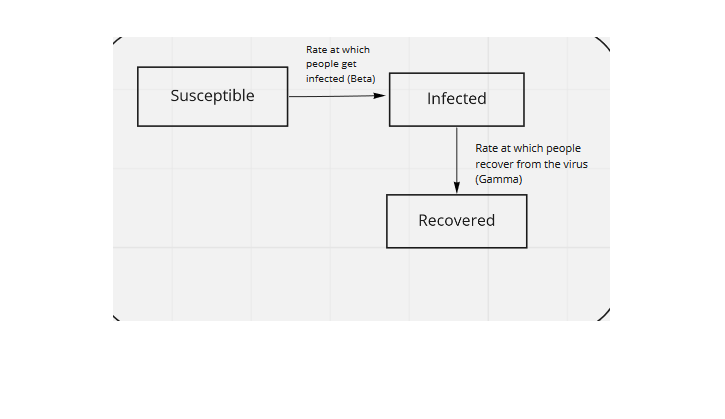

imshow(imread("model1.PNG"));

*In our model, we defined the "end" of the pandemic as the state where two conditions are met: the rate of infection is plateauing and the total rate of infection is one infected person per week or lower. *

*We set the parameters of our model by fitting our flows, Beta and Gamma, so that our simulation would closely match the data we were given. *

*We verified our model by plotting the total number of people in the system remained the same even after changing parameters such as the number of initial infected. We wanted to make sure that our system was not leaking individuals or gaining any individuals. *

### Results

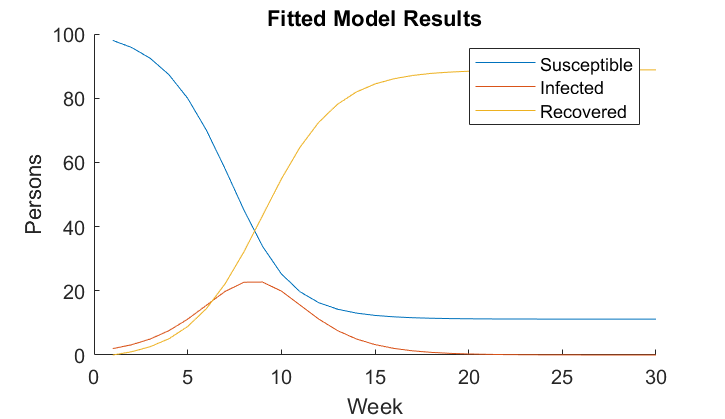

% ModelMk1:
% Parameters: i_0 (infectious people), s_0 (susceptible people), r_0
% (recovered people), beta (infection rate), and gamma (recovery rate)
% Precondition: There are i_0 = 2 infectious people, s_0 = 98 susceptible people, and
% r_0 = 0 recovered people. Beta = 1/90 and and gamma = 1/2
% Postcondition: There are the same number of people in the system at the
% end of the simulation as there were at the beginning. There are 0 people
% in the i_0 stock, signaling the end of the outbreak


% Initial state of model
% A population of 100 persons, 98 susceptible and 2 infectious people

i_0 = 2;
s_0 = 100 - i_0;
r_0 = 0;
Total = i_0 + s_0 + r_0;

beta = 1 / 90; %Infection rate
gamma = 1 / 2; %Recovery rate

[S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30); %Runs the actual simulation, storing the results in vectors

plotting; %Plots the results of the model

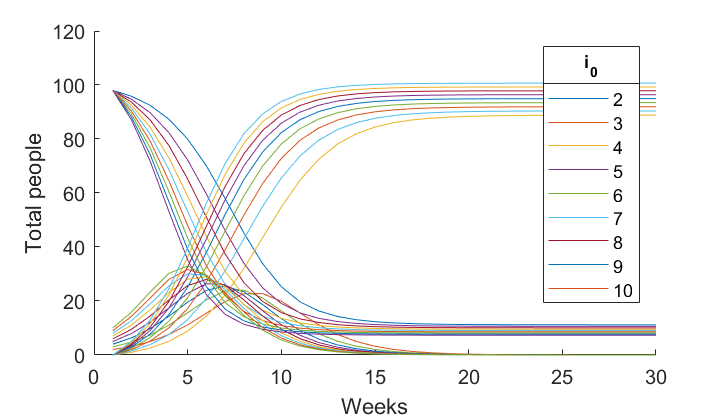

%{
Verification:
Facts: The # of people in each stock, i_0, s_0, and r_0, total to 100. The
total number of people at the end of the simulation still remains the same.
%}

% Interpretation - ModelMk1:
% Fill in here
% Need to try different total values and different i_0 values

% ModelMk2:
% Parameters: i_0 (infectious people), s_0 (susceptible people), r_0
% (recovered people), beta (infection rate), and gamma (recovery rate)
% Precondition: There are i_0 = 2 infectious people, s_0 = 98 susceptible people, and
% r_0 = 0 recovered people. Beta = 1/90 and and gamma = 1/2
% Postcondition: There are the same number of people in the system at the
% end of the simulation as there were at the beginning. There are 0 people
% in the i_0 stock, signaling the end of the outbreak

i0_sweep = 2:1:10; %Defines the sweep for i_0
i_0 = 2;
s_0 = 100 - i_0;
r_0 = 0;
Total = i_0 + s_0 + r_0; %Total # of people in the system

clf
hold on
for i_0 = i0_sweep %Parameter sweep for i_0
    [S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30);
    plot(S_fit)
    plot(I_fit)
    plot(R_fit)
end

hold off

%Plots the results of the sweep
xlabel('Weeks')
ylabel('Total people')
lgd = legend(string(i0_sweep)); 
lgd.Title.String = 'i_0';     
lgd.Location = 'northeast';   

%{
Verification:
Facts: The # of people in each stock, i_0, s_0, and r_0, total to 100. The
total number of people at the end of the simulation still remains the same.
%}

%Interpretation - ModelMk2:
%Fill in here
%Should do a parameter sweep for the number of susceptible people

### Interpretation

*The results of our updated model will hopefully be a more "true-to-life" representation of the outbreak to help predict when the flu pandemic as shown in the data will last. *

*Based on our current values, we can safely assume that if other variables are "normal", meaning that there would be no outside factors that come into play such as a vaccine or safety measures and people just continue on their normal lives, it will take between twelve and eighteen for the flu pandemic to fully cease. These results show that the number of initial infected individuals plays a significant role in the length of the infection. Increasing the number of initial infected individuals shortens the length of the outbreak, according to our model.*

*Our model is limited in that, as we mentioned in the methodology section, we did not account for variance in infection rate or recovery rate. Another limitation is that we only tested different values for the number of initial infected. We did not conduct parameter sweeping for our flows, or any other stocks. Finally, we did not account for potential reinfectivity of recovered individuals. *

*We believe the next step for both models is to do a parameter sweep of the number of suspectible on both models to test how changing variables such as the initial number of people infected, the rate at which people will get infected, and the rate at which people recover will affect our model.*